q_yogurt = 0:1:1000; % [kg/h]
t_operation = 300 * 24;
x1 = 0.85; % [percent water]
x2 = 0.05; % [percent water]
L_s = (1 - 0.85) * q_yogurt; % [kg/h], solid flow rate
Y_1 = 0;
cps = 4.0; % [kJ/kg.K]
cpw = 4.2; % [kJ/kg.K]
cpv = 1.89; % [kJ/kg.K]
cpa = 1.0312; % [kJ/kg.K]
lambda = 2510.7; % [kJ/kg]
t_yogurt_1 = 15 + 273; % [K]
t_air_1 = 150 + 273; % [K]
t_air_2 = 120 + 273; % [K]
Y_2 = 0.0213; % [kg water / kg air]

v_peripheral = 182.88; % [m/s]
N = 65000; % [rpm]
d_disk = 0.179; % [m]
P_atomizer = (1.02e-8 .* (q_yogurt .* 0.0367) .* (N .* (d_disk .* 3.28)) ^ 2) .* 0.7457; % [kw]

G_s = (L_s .* (x1 - x2)) ./ Y_2;
t_yogurt_2 = (L_s .* t_yogurt_1 .* (cps + x1 .* cpw) + G_s .* (cpa .* t_air_1 - ((cpa + Y_2 .* cpv) .* t_air_2 + Y_2 .* lambda))) / (L_s .* (cps + x2 .* cpw)) - 273; % [C]
evap_rate = (Y_2 - Y_1) .* q_yogurt;

V_air_in = 8315 .* (1 / 29 + Y_1 / 18) * (t_air_1 / 101325);
V_air_out = 8315 .* (1 / 29 + Y_2 / 18) * (t_air_2 / 101325);
V_air_avg = (V_air_in + V_air_out) / 2; % [m^3/kg dry air]

D_p = 100e-6; % [m]
rho_yogurt = 1.03; % [kg/m^3]
rho_air = 0.865; % [kg/m^3]
g = 9.8; % [m/s^2]
mu_air = 23.329e-6; % [N/m]

v_s = D_p .^ 2 .* (rho_yogurt - rho_air) .* g ./ (18 .* mu_air); % [m/s]

Re = D_p .* v_s .* rho_yogurt ./ mu_air % if less than 2, operating velocity is 2 * settling velocity

Re = 1.7001e-04

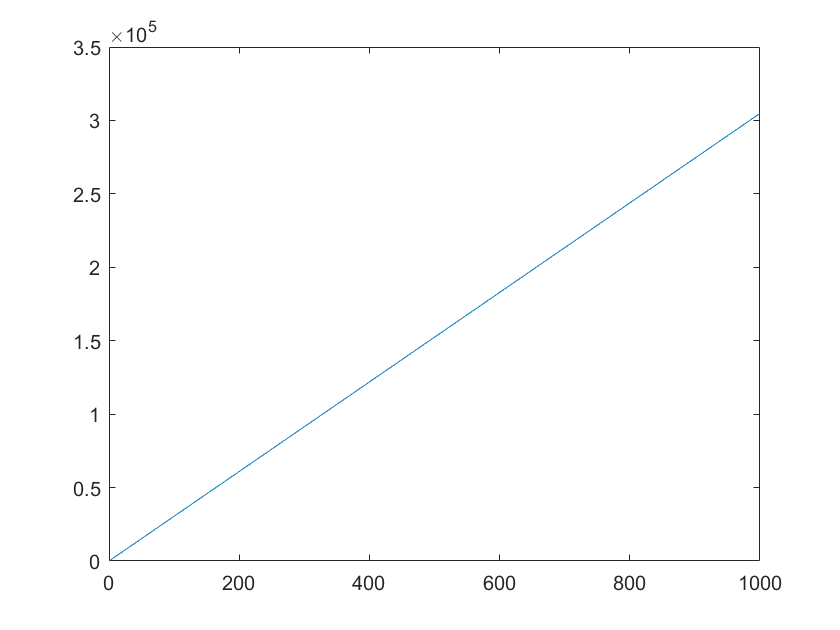

v_a = 2 .* v_s;

t_d = 50 .* sqrt(x1);

V = G_s .* V_air_avg .* t_d; % m^3

plot(q_yogurt, V)


P_heat = G_s .* cpa .* (t_air_1 - t_air_2); % kJ/h

C_electricity = 0.0033; % [$/kwh]
C_wage = 45; % [$/h]
C_energy = (P_atomizer + P_heat) .* t_operation .* C_electricity;  % [$ / year]
C_labor = t_operation .* C_wage; % [$ / year]
C_variable = C_energy + C_labor; % [$ / year]
max(V)

ans = 3.0480e+05

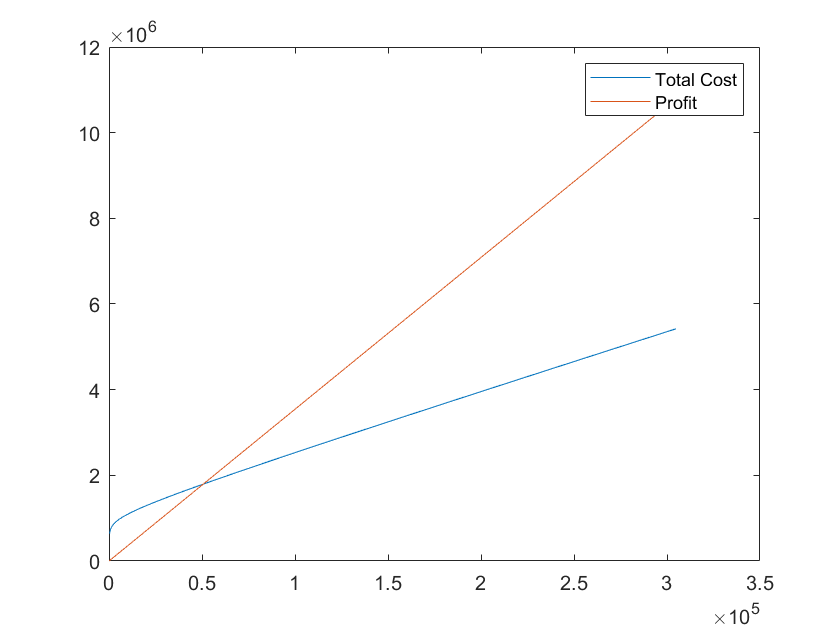

C_equip = 188371 * log(V) - 442423; % [$]
C_maintenance = 0.15 .* C_equip; % [$ / year]
C_depreciation = (C_equip) ./ 10; % [$ / year]
C_fixed = present_annual(C_equip, 0.2, 10) + C_maintenance ...
    + C_depreciation; % [% / year]
C_annual = C_fixed + C_variable; % [$ / year]

Profit = 30 .* q_yogurt .* x2 .* t_operation;

C_equip_energy = C_equip + C_energy;

plot(V, C_annual)
hold on
plot(V,Profit)
hold off
legend('Total Cost', 'Profit')

function A = present_annual(P, i, N)
    % capital recovery
    A = P * (i * (1 + i) ^ N) / (((1 + i) ^ N) - 1);
end
